clear all
clc
digits(4)

Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');

% Massa asta
m_a = sym('3.5');

% Massa uomo (da far variare poi)
m_c = sym('70');
w_c = sym('154.3234');

% Massa carello(base) + batterie
m_b = sym('34.4');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante gravitazionale
g = sym('9.81');

Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo (TODO: lungo asse z????)
J_c = 0.5 * m_c * (0.25 ^ 2 + 0.35 ^ 2);

% Inerzia della singola ruota
J_r = sym('0.1452');

Definizione delle altezze [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Posizione baricentro corpo umano
h_c = sym('1.70'); % Altezza uomo
z_c = 0.55 * h_c;

% Raggio ruota
r_r = sym('0.22')

$$r\_r = 0.22$$

Definizione delle costanti geometriche a e beta (come in immagine)

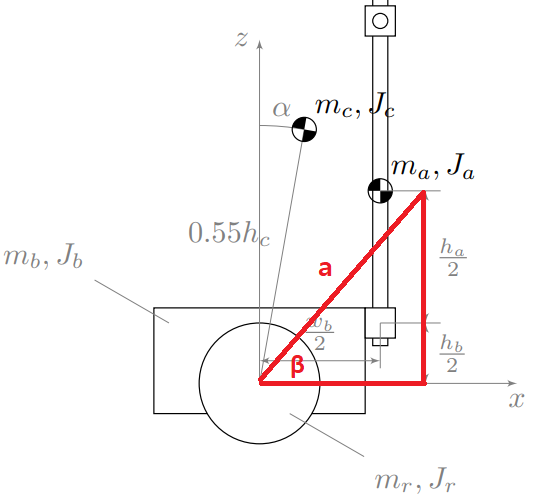

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;
a = vpa(sqrt((temp_1)^2 + (temp_2)^2));
beta = vpa(atan(temp_1 / temp_2));

Definizione delle variabili

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro

% Coordinate libere
syms x(t); % posizione carrello
vel = diff(x, t)

$$vel(t) = \frac{\partial }{\partial t}x\left(t\right)$$

syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t)

$$vel\_ang(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

Definizione dell'energia cinetica del sistema (indipendente dal tempo)

syms q_1 q_1_p q_2 q_2_p
% Energia cinetica singola ruota
T_r = 0.5 * m_r * q_1_p^2 + vpa(0.5 * J_r) * (q_1_p / r_r)^2

$$T\_r = 3.0\,{q_{1,p}}^{2}$$


% Energia cinetica base (contributo energia cinetica "lineare" e
% rotazionale)
T_b = vpa(0.5 * m_b) * q_1_p^2 + vpa(0.5 * J_b) * q_2_p ^ 2

$$T\_b = 17.2\,{q_{1,p}}^{2}+0.3333\,{q_{2,p}}^{2}$$


% Energia cinetica asta (contributo energia cinetica "lineare" e
% rotazionale)
T_a = vpa(0.5 * m_a) * q_1_p^2 + vpa(0.5 * J_a) * q_2_p ^ 2

$$T\_a = 1.75\,{q_{1,p}}^{2}+0.08345\,{q_{2,p}}^{2}$$


% Energia cinetica corpo (contributo energia cinetica "lineare" e
% rotazionale)
T_c = vpa(0.5 * m_c) * q_1_p^2 + vpa(0.5 * J_c) * q_2_p ^ 2

$$T\_c = 35.0\,{q_{1,p}}^{2}+3.238\,{q_{2,p}}^{2}$$


T = 2 * T_r + T_b + T_a + T_c

$$T = 59.95\,{q_{1,p}}^{2}+3.654\,{q_{2,p}}^{2}$$

Definizione dell'energia potenziale

% Energia potenziale base
U_b = - vpa(m_b * g * z_c * cos(q_2)) 

$$U\_b = -315.5\,\cos\left(q_{2}\right)$$


% Energia potenziale asta (manubrio)
U_a = vpa(m_a * g * a * cos(beta + q_2))

$$U\_a = 28.78\,\cos\left(q_{2}+1.268\right)$$


% Energia potenziale corpo
U_c = vpa(m_c * g * z_c * cos(alpha + q_2))

$$U\_c = 642.1\,\cos\left(\alpha +q_{2}\right)$$


U = U_b +  U_a + U_c

$$U = 28.78\,\cos\left(q_{2}+1.268\right)+642.1\,\cos\left(\alpha +q_{2}\right)-315.5\,\cos\left(q_{2}\right)$$

Definizione della Lagrangiana

L = T - U

$$L = 59.95\,{q_{1,p}}^{2}+3.654\,{q_{2,p}}^{2}-28.78\,\cos\left(q_{2}+1.268\right)-642.1\,\cos\left(\alpha +q_{2}\right)+315.5\,\cos\left(q_{2}\right)$$

Calcolo delle equazioni di moto

% theta -> ang_car -> q_2   theta'-> vel_ang_car -> q_2_p

% dL/dq_2
dL_dq2= diff(L, q_2)

$$dL\_dq2 = 28.78\,\sin\left(q_{2}+1.268\right)+642.1\,\sin\left(\alpha +q_{2}\right)-315.5\,\sin\left(q_{2}\right)$$

dL_dq2_t = subs(dL_dq2, {q_1, q_1_p, q_2, q_2_p}, {x, vel, theta, vel_ang})

$$dL\_dq2\_t = 28.78\,\sin\left(\theta \left(t\right)+1.268\right)+642.1\,\sin\left(\alpha +\theta \left(t\right)\right)-315.5\,\sin\left(\theta \left(t\right)\right)$$


% dL/dq_2_p
dL_dq2p= diff(L,q_2_p)

$$dL\_dq2p = 7.309\,q_{2,p}$$

dL_dq2p_t = subs(dL_dq2p, {q_1, q_1_p, q_2, q_2_p}, {x, vel, theta, vel_ang})

$$dL\_dq2p\_t = 7.309\,\frac{\partial }{\partial t}\theta \left(t\right)$$


% d(dL_dq1p)/dt
dL_dq2p_dt = diff(dL_dq2p_t, t)

$$dL\_dq2p\_dt = 7.309\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$


dL_dq2p_dt - dL_dq2p_t == 0

$$ans = 7.309\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-7.309\,\frac{\partial }{\partial t}\theta \left(t\right)=0$$

**guarda qui piffo prima di passare dopo**

clc
clear
syms t
syms x x_f(t)
k = cos(x^2 * x_f)

$$k(t) = \cos\left(x^{2}\,x_{f}\left(t\right)\right)$$

temp3 = diff(k, x)

$$temp3(t) = -2\,x\,\sin\left(x^{2}\,x_{f}\left(t\right)\right)\,x_{f}\left(t\right)$$

%temp = diff(k,t)
vel = diff(x_f, t)

$$vel(t) = \frac{\partial }{\partial t}x_{f}\left(t\right)$$

temp2 = subs(temp3,{x},{vel})

$$temp2(t) = -2\,\sin\left(x_{f}\left(t\right)\,{\left(\frac{\partial }{\partial t}x_{f}\left(t\right)\right)}^{2}\right)\,x_{f}\left(t\right)\,\frac{\partial }{\partial t}x_{f}\left(t\right)$$


diff(temp2,t)

$$ans(t) = \begin{array}{l} -2\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}x_{f}\left(t\right)\right)}^{2}-2\,\sigma_{1}\,x_{f}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{f}\left(t\right)-2\,\cos\left(x_{f}\left(t\right)\,{\left(\frac{\partial }{\partial t}x_{f}\left(t\right)\right)}^{2}\right)\,x_{f}\left(t\right)\,\left({\left(\frac{\partial }{\partial t}x_{f}\left(t\right)\right)}^{3}+2\,x_{f}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{f}\left(t\right)\,\frac{\partial }{\partial t}x_{f}\left(t\right)\right)\,\frac{\partial }{\partial t}x_{f}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(x_{f}\left(t\right)\,{\left(\frac{\partial }{\partial t}x_{f}\left(t\right)\right)}^{2}\right) \end{array}$$

If you want to differentiate L with respect to q, q must be a variable. You can use `subs` to replace it with a function and calculate  the derivative later:

syms t x teta vel omega h L1 M1        % variables
%valori di T e U a caso, per fare una prova
T = 1/2*5*vel^2

$$T = \frac{5\,{\mathrm{vel}}^{2}}{2}$$

U = 5*10*h

$$U = 50\,h$$

L = T-U

$$L = \frac{5\,{\mathrm{vel}}^{2}}{2}-50\,h$$

%dL/dq'
dLdvel= diff(L,vel)

$$dLdvel = 5\,\mathrm{vel}$$

%dL/dq
dLdx = diff(L,x)

$$dLdx = 0$$

%creo alrtre variabili dipendenti dal tempo questa volta
syms x_f(t) teta_f(t) h_f(t)  % functions
%calcolo le derivate delle variabili di cui sopra
vel_f(t)= diff(x_f,t)

$$vel\_f(t) = \frac{\partial }{\partial t}x_{f}\left(t\right)$$

omega_f(t)= diff(teta_f,t)

$$omega\_f(t) = \frac{\partial }{\partial t}{\mathrm{teta}}_{f}\left(t\right)$$

dh_f(t) = diff(h_f,t)

$$dh\_f(t) = \frac{\partial }{\partial t}h_{f}\left(t\right)$$

%sostituisco le variabili dipendenti dal tempo a qelle indipendenti
dLdqt_f= subs(dLdvel,{x,teta,h,vel,omega},{x_f,teta_f,h_f,vel_f,omega_f})

$$dLdqt\_f = 5\,\frac{\partial }{\partial t}x_{f}\left(t\right)$$

dLdq_f = subs(dLdx,{x,teta,h,vel,omega},{x_f,teta_f,h_f,vel_f,omega_f})

$$dLdq\_f = 0$$

dLdveldt = diff(dLdqt_f,t)

$$dLdveldt = 5\,\frac{\partial^{2}}{\partial t^{2}}x_{f}\left(t\right)$$

%risolvo l'equazione
ris = dsolve(dLdveldt-dLdq_f==0)

$$ris = C_{2}+C_{1}\,t$$

%non so ancora interpretare il risultato, immagino sia
%la risoluzione di una equazione differenziale
